# EXERCISE #1 : Build a simplistic WLAN Scenario Simulation

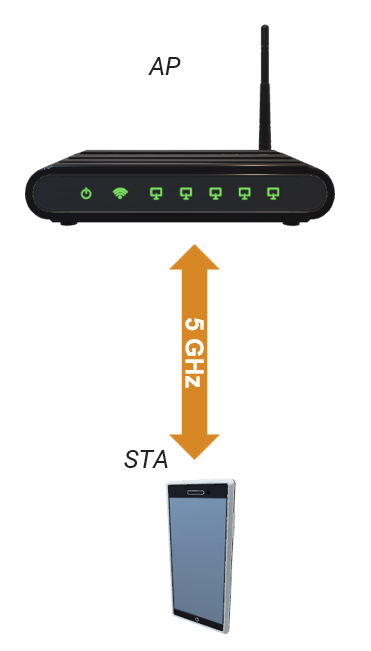

WLAN Network with one AP and STA 

## 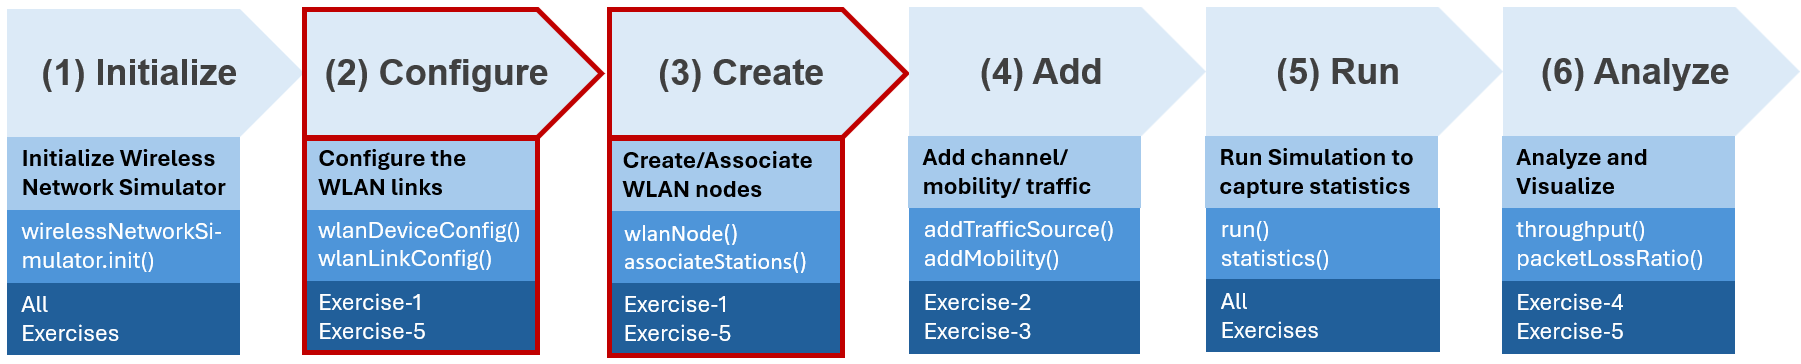

Workflow to perform WLAN Network Modeling 

### In this exercise, you will learn how to configure and create WLAN nodes and set up a wireless network. 

### **Please work on the tasks located in the "Exercises" folder and set the "Exercises" folder as the current folder **

### Part 1 : AP generates beacon frames only

- Beacon is set to run at 10x TU

- Simulation time = (100x TU)

- Explore objects used in Network Simulator

- Explore measurements

### Part 2 : AP generates DL traffic 

- Explore Statistics

Copyright 2024-2025 The MathWorks, Inc

#### Cleanup

clear;
format shortEng;

### Define traffic type

- Beacon Only (default)

- Bidirectional

- DL

- UL

#### `Part 1 --> Please use "Beacon Only"`

#### `Part 2 --> Please select "DL"`

trafficType = "off"

### General settings

- `5 GHz band`

- `20 MHz wide channel`

- `Channel 36`

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html)

band        = 5;
bandwidth   = 20e6;
channel     = 36;
fc          = wlanChannelFrequency(channel,band);

txPower     = 0.0; % dBm - Use 0 dBm to make calculations easy...
txGain      = 0.0; % dB  - Will use this field to mimic additional attenuation

- `Time Unit = 1024us`

TU              = 1024e-6; % Transmition Unit(TU) in WLAN is 1024 us 
simulationTime  = 100*TU;  % Simulation time is set to 100*TU 

### Geometry

- Define position of AP and STA

% Adjust relative positions of AP and STA to change SNR
% range -15m, +15m in X and Y (limited by plotStations utility function, but could be updated if needed)
AP_pos  = [0,0,0];
STA_pos = [5,0,0];

`Utility function to plot AP, STA, distance and fspl`

[dist, atten] = plotStations(AP_pos,STA_pos,fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

# Task #1/4 Create a device configuration for WLAN AP

- 802.11n type

- Sends a beacon each 10x TU (10.24 ms)

- AP is located at [0, 0, 0]

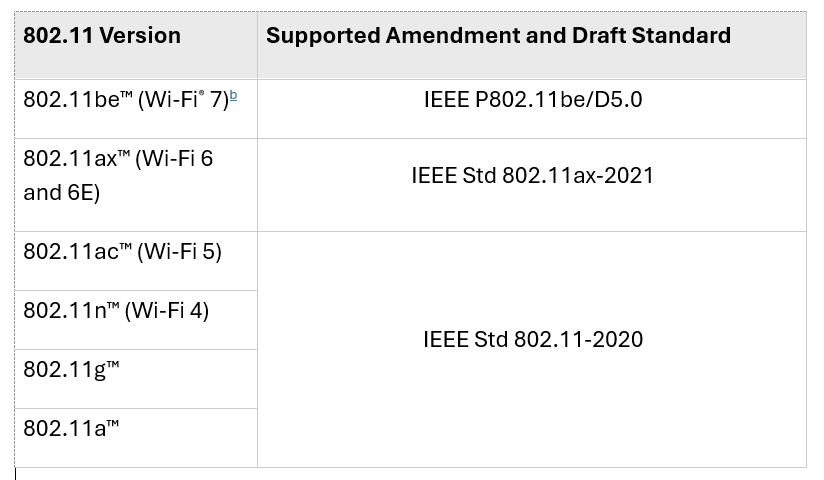

[802.11 standards supported by MATLAB for the WLAN network modeling](https://www.mathworks.com/help/releases/R2024b/wlan/ug/802-11-standards-supported-by-wlan-toolbox-for-system-level-simulation.html)

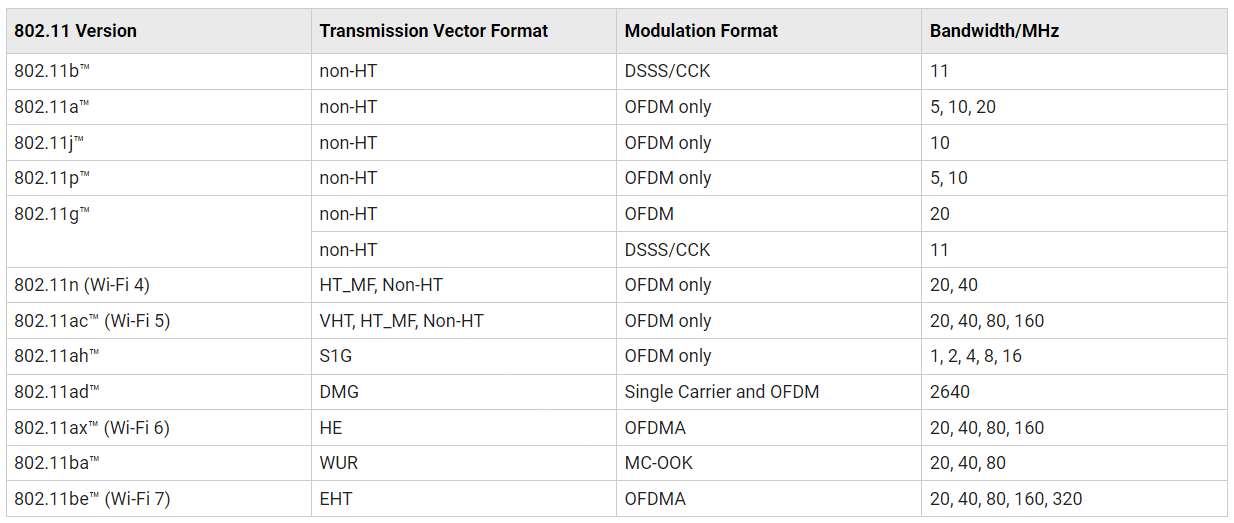

[802.11 standards supported by MATLAB for the WLAN link modeling](https://www.mathworks.com/help/releases/R2024b/wlan/gs/802-11-standards-supported-by-wlan-toolbox-for-phy-modeling.html)

% Use wlanDeviceConfig() function to configure the AP
% Write configuration in a variable named "APCfg"
% Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% "BandAndChannel",[band,channel]
% "ChannelBandwidth",bandwidth
% "TransmissionFormat","HT-Mixed"
% "TransmitPower",txPower
% "TransmitGain",txGain
% "BeaconInterval",10
% "Mode","AP"
% "MCS",3

% <enter code below>
% APCfg =     

Get total attenuation is TransmitGain has been set to a value different from 0

totalAttenuation = atten - APCfg.TransmitGain

# Task #2/4 Create a WLAN node with AP configurations defined earlier 

Note: All nodes on the network must have same MAC and PHY abstractions  

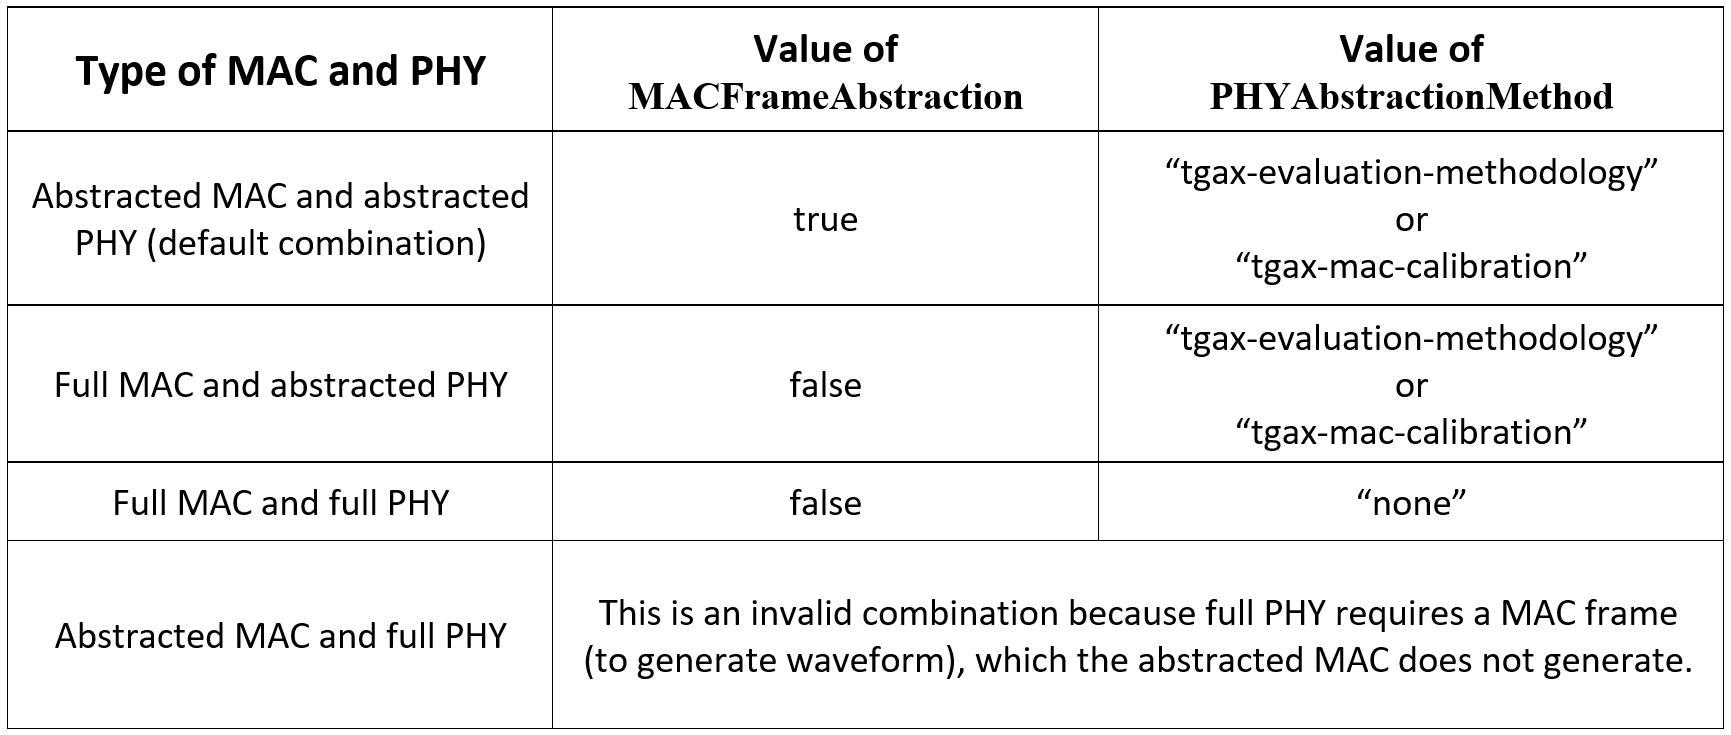

% Use wlanNode() function to instantiate the AP using the configuration you
% have just created
% Name the variable "AP"
% Note : use the following values to start with
% "DeviceConfig",APCfg
% "Position", AP_pos
% "PHYAbstractionMethod","tgax-evaluation-methodology"
% "MACFrameAbstraction",false

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

% <enter code below>
% AP = 

### Create a simple STA

- 802.11n type

- Similar as the creation of the AP

- Code is provided for you

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...    
    "MCS",3);

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

# Task #3/4 Associate AP with STA

% Use associateStations() function to define associations between AP's and STA's
% Hint: Click the link below and and see the "Syntax" section.

### [Help on Associating Station ](https://www.mathworks.com/help/wlan/ref/wlannode.associatestations.html)

% AssociateStations is a method of the wlanNode object
% Note : please use "FullBufferTraffic" = trafficType in the function call

% <enter code below>
% 

`Note`` : `

- `As of now, Full buffer configuration generates traffic in AC0.`

- `As full buffer configuration generates AC0 traffic, you can still instantiate traffic of other ACs (AC1, AC2, AC3) using ‘addTrafficSource’ (pls see next exercise)`

- `For AC0 traffic, you can either use full buffer configuration or install traffic of AC0 using ‘addTrafficSource’`

- `Traffic generation is implementation dependent and not part of EDCA and QoS. EDCA and QoS define how the generated traffic is differentiated, prioritized, and queued. Full buffer just represents a traffic pattern where a node always has data to send at any point of time. This pattern can be applied for any Access Category, but we support it for only AC0 in our simulation.`

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

addNodes(networkSimulator,{AP, STA})
run (networkSimulator,simulationTime)

# Task #4/4 Visualize statistics at AP

% Use statistics() function to get statistics (APP, MAC, PHY) for AP and
% STA
% Create a variable names APStatistics 
% Hint:  click the link below see the "Syntax" section.

### [Help on statistics](https://www.mathworks.com/help/wlan/ref/wlannode.statistics.html)

% <enter code below>
% APStatistics = 

### APP Layer statistics

APStatistics.App

- `Explore the list of statistics the networkSimulator object maintains`

- `We have not defined any traffic so far, only TransmittedBeaconFrames should be populated`

### MAC Layer Statistics

APStatistics.MAC

- `Ability to extract a specific element :`

APStatistics.MAC.TransmittedBeaconFrames

### PHY Layer Statistics

APStatistics.PHY

### Explore statisctics at the STA

STAStatistics = statistics(STA);
STAStatistics.MAC
STAStatistics.MAC.ReceivedBeaconFrames
STAStatistics.PHY

#### Suggested Experiment:

#### #1

#### Refer to the provided table to adjust the following parameters:

- **For the scenario where the AP (Access Point) generates only beacon frames, set the AP’s position to **`[-25, -25, 0]`** and the STA’s (Station) position to **`[25, 25, 0]`**.**

- **Increase the distance between the AP and STA so that the total attenuation causes the received signal to fall below the receiver’s minimum input sensitivity level.**

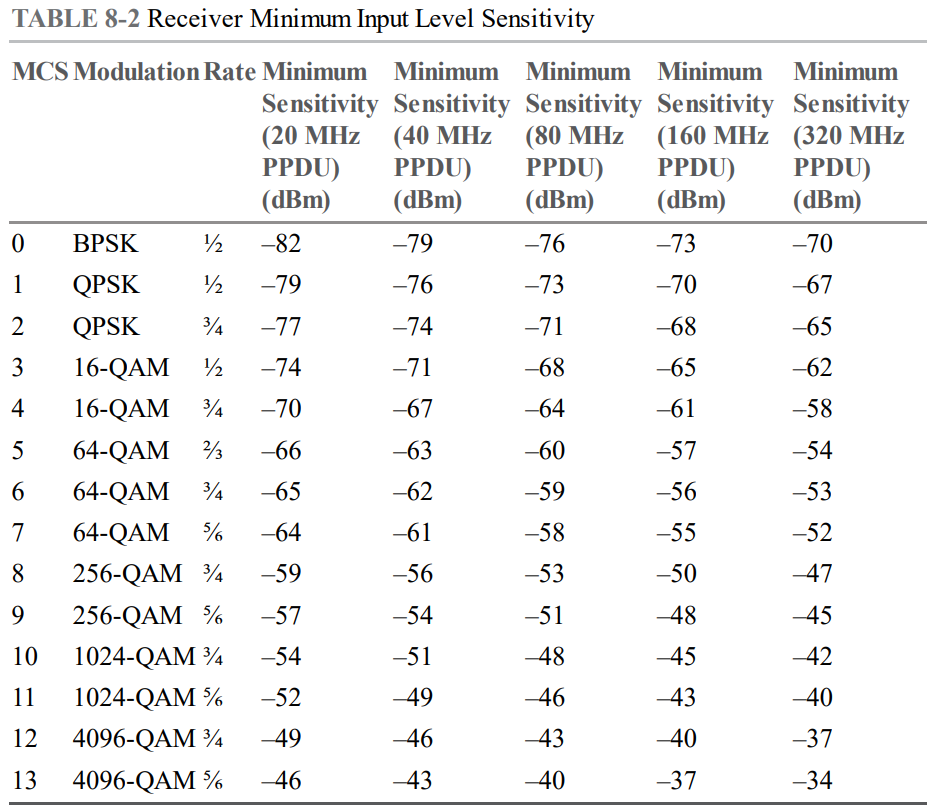

#### #2

#### For the scenario where the AP generates downlink traffic:

- **Set the AP’s position to **`[-10, -10, 0]`** and the STA’s position to **`[10, 10, 0]`**.**

- **In the AP device configuration, set the MCS (Modulation and Coding Scheme) to 6.**

- **Observe and record how statistics such as # of retransmission change as a result.**

- **Then, gradually move the AP and STA closer together to reduce # of retransmission, and note the changes in the observed statistics**.

### Further Exploration

- [https://www.mathworks.com/help/releases/R2024b/wlan/ug/getting-started-with-wlan-system-level-simulation-in-matlab.html](https://www.mathworks.com/help/releases/R2024b/wlan/ug/getting-started-with-wlan-system-level-simulation-in-matlab.html)